# 一、训练YOLOv2用于检测苜蓿花

注：①图像不需要统一大小②只可以检测单目标物体

## 1.1 导入数据

Load the training data for vehicle detection into the workspace.

clear;clc;
% 第一次使用需要自己进行标注数据，并把它保存为gTruth，否则会出错。
load('gTruth.mat');                               %标记的gTruth
trainingfiles = gTruth.DataSource.Source;         %图像位置
traininglabel = gTruth.LabelData;                 %图像标签

Create an imageDatastore using the files from the table.

imagesize = [227 277 3] ;
imgfiles = imageDatastore(trainingfiles);
% trainfiles = augmentedImageDatastore(imagesize,imgfiles,"ColorPreprocessing","gray2rgb");%灰度图像专用

Create a boxLabelDatastore using the label columns from the table.

imglabel = boxLabelDatastore(traininglabel);
% trainlabels = augmentedImageDatastore(imagesize,imgfiles,"ColorPreprocessing","gray2rgb");%灰度图像专用

Combine the datastores.

ds = combine(imgfiles, imglabel);

## 1.2 加载Yolov2模型

Load a preinitialized YOLO v2 object detection network.

net = load('yolov2VehicleDetector.mat');
lgraph = net.lgraph

lgraph =   LayerGraph with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'input'}
    OutputNames: {'yolov2OutputLayer'}


lgraph.Layers

ans =   25×1 Layer array with layers:

     1   'input'               Image Input                128×128×3 images
     2   'conv_1'              Convolution                16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'BN1'                 Batch Normalization        Batch normalization
     4   'relu_1'              ReLU                       ReLU
     5   'maxpool1'            Max Pooling                2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'              Convolution                32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     7   'BN2'                 Batch Normalization        Batch normalization
     8   'relu_2'              ReLU                       ReLU
     9   'maxpool2'            Max Pooling                2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'conv_3'              Convolution     

## 1.3 设置训练参数

options = trainingOptions('sgdm',...
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',32,...
          'MaxEpochs',100,...
          'Shuffle','never',...
          'VerboseFrequency',10,...
          'CheckpointPath',tempdir);

## 1.4 训练Yolov2模型

Train the YOLO v2 network.

[detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options)

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* flower

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         3.17 |         10.1 |          0.0010 |
|       2 |          10 |       00:00:37 |         1.78 |          3.2 |          0.0010 |
|       4 |          20 |       00:01:15 |         1.54 |          2.4 |          0.0010 |
|       6 |          30 |       00:01:50 |         1.35 |          1.8 |          0.0010 |
|       8 |          40 |       00:02:25 |         1.26 |          1.6 |          0.0010 |
|  

detector =   yolov2ObjectDetector with properties:

            ModelName: 'flower'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [128 128]
          AnchorBoxes: [4×2 double]
           ClassNames: flower


info = struct with fields:
     TrainingLoss: [1×500 double]
     TrainingRMSE: [1×500 double]
    BaseLearnRate: [1×500 double]


## 1.5 绘制训练模型损失曲线

You can verify the training accuracy by inspecting the training loss for each iteration.

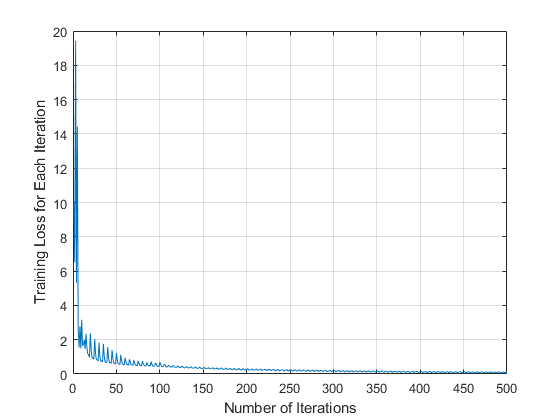

figure
plot(info.TrainingLoss)
grid on
xlabel('Number of Iterations')
ylabel('Training Loss for Each Iteration')

## 1.6 保存模型

save("Yolo2Model.mat","detector");
save("TrainedInfo.mat","info");